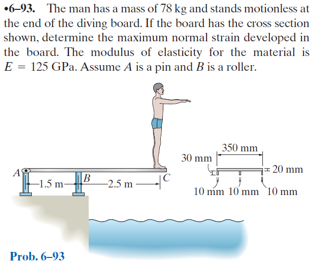

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-93P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-93P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

M = 78*u.kg;
g = 9.81*u.m/u.s^2;
W = rewrite(M*g, u.N);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 1.5*u.m);
b = b.add('concentrated', 'force', -W, 4*u.m);
b.E = 125*u.GPa;
b.L = 4*u.m;

# section properties

yc = [15 15 15 40]*u.mm;
Ac = [10*30 10*30 10*30 350*20]*u.mm^2;
Ic = [10*30^3 10*30^3 10*30^3 350*20^3]/12*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{1923166096064512\,x\,\left(2\,x-3\,m\right)\,\left(2\,x+3\,m\right)}{3615837522784711155}\,\frac{1}{m^{2}} & \text{ if }x\leq \frac{3}{2}\,m\\ \frac{1923166096064512\,\left(2\,x-3\,m\right)\,\left(2\,x^{2}-21\,x\,m+12\,m^{2}\right)}{6026395871307851925}\,\frac{1}{m^{2}} & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{1923166096064512\,\left(3\,m^{2}-4\,x^{2}\right)}{1205279174261570385}\,\frac{1}{m^{2}} & \text{ if }x\leq \frac{3}{2}\,m\\ \frac{1923166096064512\,\left(4\,x^{2}-32\,x\,m+29\,m^{2}\right)}{2008798623769283975}\,\frac{1}{m^{2}} & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{12753\,x}{10}\,N & \text{ if }x\leq \frac{3}{2}\,m\\ \frac{38259\,\left(x-4\,m\right)}{50}\,N & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{12753}{10}\,N & \text{ if }x\leq \frac{3}{2}\,m\\ \frac{38259}{50}\,N & \text{ if }\frac{3}{2}\,m<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & -1275.3\,N\\ \mathrm{Rb} & 2040.48\,N \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

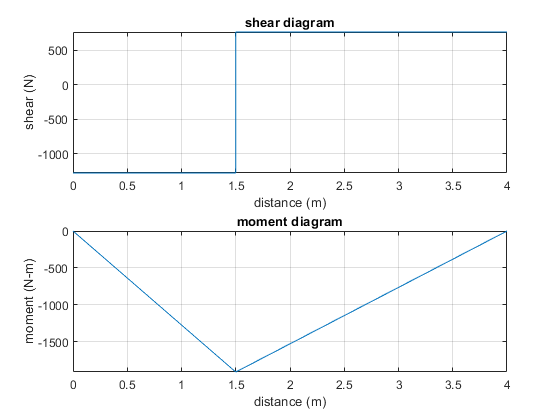

beam.shear_moment(m, v, [0 b.L], {'N' 'm'});

# maximum stress and strain

M_max = -m(1.5*u.m);
M_max_vpa = vpa(M_max) %#ok<NASGU> 

$$M\_max\_vpa = 1912.95\,N\,m$$

c = symmax([yn 50*u.mm-yn]);
b.I = rewrite(b.I, u.mm);
sigma_max = rewrite(M_max*c/b.I, u.MPa);
sigma_max_vpa = vpa(sigma_max, 4) %#ok<NASGU> 

$$sigma\_max\_vpa = 88.92\,\mathrm{MPa}$$

e_max = simplify(sigma_max/b.E);
e_max_vpa = vpa(e_max, 4) %#ok<NASGU> 

$$e\_max\_vpa = 0.0007114$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear M_max_vpa sigma_max_vpa e_max_vpa;